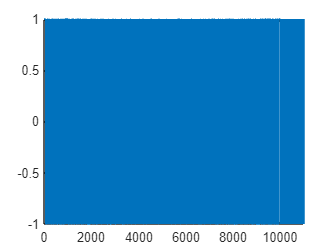

clear all
close all

pis = ones(1000,1)'*pi;
f = [linspace(0.001,pi,10000),pis];
t=1:1:length(f);
wfm = sign(cos(f.*t));
plot(wfm)

% Digital waveform generation and stability test

% Parameters
sample_rate = 100000;  % Specify your desired sample rate in Hz
duration = 10;       % Specify the duration of the signal in seconds

% Time vector
t = 0:1/sample_rate:duration-1/sample_rate;

digital_frequency = logspace(log10(1),log10(0.5 * sample_rate),length(t))

digital_frequency = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


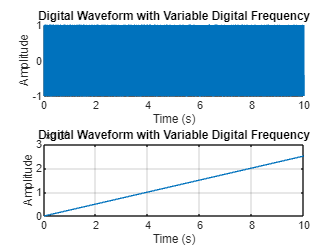

% Generate digital frequency varying from 0 to half the sample rate
digital_frequency = 0.25 * sample_rate * t / duration;

%digital_frequency = [digital_frequency,ones(1, length(t))*sample_rate/2];
%t = 0:1/sample_rate:2*duration-1/sample_rate;

% Generate digital waveform (sine wave)
digital_waveform = sign(cos(2 * pi * digital_frequency .* t));

%digital_waveform = 0.5 * cos(2 * pi * 1600 .* t);

% Plot the digital waveform
figure;
subplot(2, 1, 1);
plot(t, digital_waveform);
title('Digital Waveform with Variable Digital Frequency');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(2, 1, 2);
plot(t, digital_frequency);
title('Digital Waveform with Variable Digital Frequency');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Compare IIRfilter with the implemented fixed point with late multiply pipelined for function%
%%calculate wc from alpha, alpha = 1-(1-sin(wc))/cos(wc);
%wc = asec((-alpha^2 + 2*alpha-2)/(2*(alpha-1)));
%fc=wc/(2*pi)*fs
%tau=1/(2*pi*fc)

% Time_per_step = 0.001;
% tau = Time_per_step/6.91; %for 99.9% settling of first order filter
% fc = 1/(2*pi*tau);
% wc = fc/fs * 2 * pi;
% alpha = 1-(1-sin(wc))/cos(wc);
alpha = 2^-26;
wc = asec((-alpha^2 + 2*alpha-2)/(2*(alpha-1)))

wc = 2.1073e-08

fc=wc/(2*pi)*sample_rate

fc = 3.3539e-04

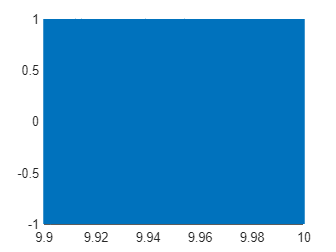

tau=1/(2*pi*fc);
figure()
plot(t(end-10000:end), digital_waveform(end-10000:end));

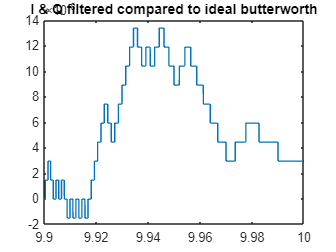

[digital_waveform_flt, ]  = tustin_pipeline_fp_opt(digital_waveform(end-10000:end), zeros(1,length(digital_waveform(end-10000:end))), alpha);
figure()
plot(t(end-10000:end), digital_waveform_flt);
title('I & Q filtered compared to ideal butterworth');

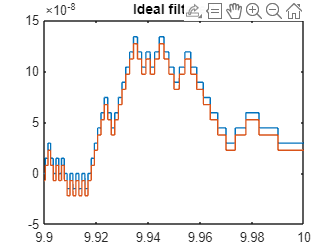

tustin_num = alpha/2*[1 1];
tustin_den = [1 -(1-alpha)];
tustin_iir = dsp.IIRFilter('Numerator',tustin_num,'Denominator',tustin_den);
fvtool(tustin_iir);

digital_waveform_flt_ideal = tustin_iir(double(digital_waveform(end-10000:end)'))';
reset(tustin_iir)
figure()
plot(t(end-10000:end), digital_waveform_flt);
hold on;
plot(t(end-10000:end), digital_waveform_flt_ideal);
title('Ideal filtered');